# Deep Interpolation

This example imports and uses the deep interpolation model in MATLAB.

## Import and Assemble Model

Import the trained model.

importednet = importKerasLayers('2019_09_11_23_32_unet_single_1024_mean_absolute_error_Ai93-0450.h5','ImportWeights',true);

Placeholders layers were added.  We'll replace the output with an [`maeRegressionLayer`](https://www.mathworks.com/help/deeplearning/ug/define-custom-regression-output-layer.html) from the documentation to make predictions.

placeholders = findPlaceholderLayers(importednet);
disp(placeholders)

  PlaceholderOutputLayer with properties:

    Name: 'conv2d_10_OutputLayer_PLACEHOLDER'

   Learnable Parameters
    No properties.

   State Parameters
    No properties.

  Show all properties



regressionnet = replaceLayer(importednet, placeholders.Name , maeRegressionLayer);
deepinterpnet = assembleNetwork(regressionnet)

deepinterpnet =   DAGNetwork with properties:

         Layers: [33×1 nnet.cnn.layer.Layer]
    Connections: [36×2 table]
     InputNames: {'input_1'}
    OutputNames: {'MAE Regression'}


## Analyze Network

Optionally analyze the network

if true
    analyzeNetwork(deepinterpnet)
end

## Import Sample TIFF Volume

ophys = tiffreadVolume('ophys_tiny_761605196.tif');

## Make Prediction

The network expects an input of size:

regressionnet.Layers(1).InputSize

ans =    512   512    60


The size of the *ophys* image is:

ophyssz = size(ophys)

ophyssz =    512   512   100


Make prediction with the equivalent size:

firstslice = ceil(9);
disp("before prediction")

before prediction


try
    ophysinterp = predict(deepinterpnet, ophys(:,:,firstslice:(firstslice+59)));
catch
    warning('Problem using predict.  Returning null.');
    ophysinterp = [];
end

Show interpolation result:

disp("after prediction")

after prediction


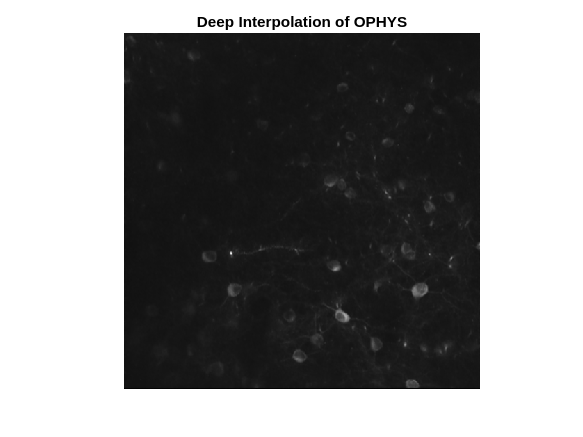

imshow(ophysinterp, [])
title("Deep Interpolation of OPHYS")